clear

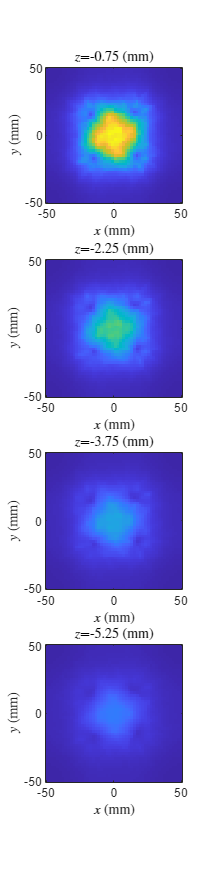

load("Sensivity_0130-0951.mat")

z = unique(element_positions(3,:));
z = sort(z, 'descend');

S_norm = vecnorm(S);

figure('Position',[10 10 300 300*length(z)])
for k = 1:length(z)
    mask = element_positions(3,:) == z(k);
    c = reshape(S_norm(mask), sqrt(sum(mask)),[]);

    subplot(length(z),1,k)
    imagesc([-50 50],[-50 50], c.', [0 max(S_norm)])
    axis square xy
    title(sprintf('$z$=%g (mm)',z(k)*1e3), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
end